**Bisection Method**:

Suppose f is a continuous function defined on the interval [a, b], with f(a) and f(b) of opposite sign. The Intermediate Value Theorem implies that a number p exists in (a, b) with f(p) = 0. The method calls for a repeated halving (or bisecting) of subintervals of [a, b] and, at each step, locating the half containing p.

 To begin, set a1 = a and b1= b, and let p1 be the midpoint of [a, b]; that is

                               
$$p_1 =a_1 +\frac{b_1 -a_1 }{2}=\frac{a_1 +b_1 }{2}$$


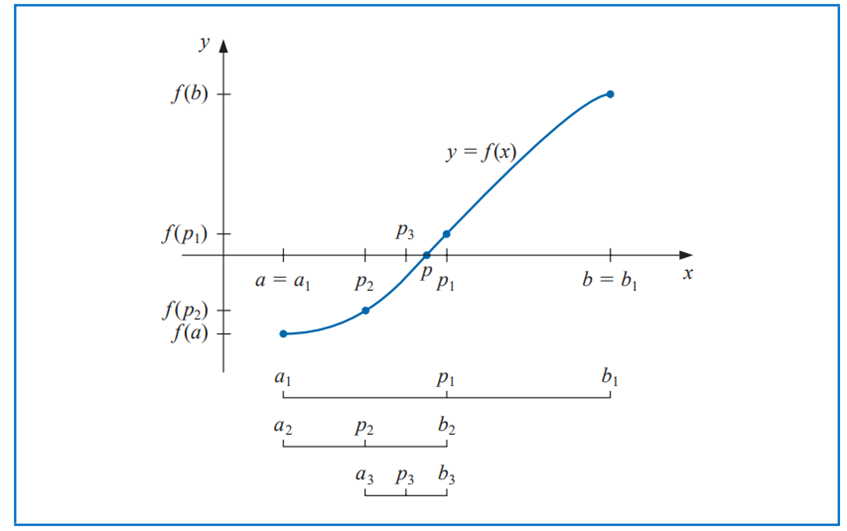

• If f(p1) = 0, then p = p1, and we are done.

 • If f(p1) ≠ 0, then f(p1) has the same sign as either f(a1) or f(b1). 

• If f(p1) and f(a1) have the same sign, p ∈ (p1, b1). Set a2 = p1and b2 = b1. 

• If f(p1) and f(a1) have opposite signs, p ∈ (a1, p1). Set a2 = a1 and b2 = p1.

Then reapply the process to the interval [a2, b2].

Thus the algorithm becomes- 

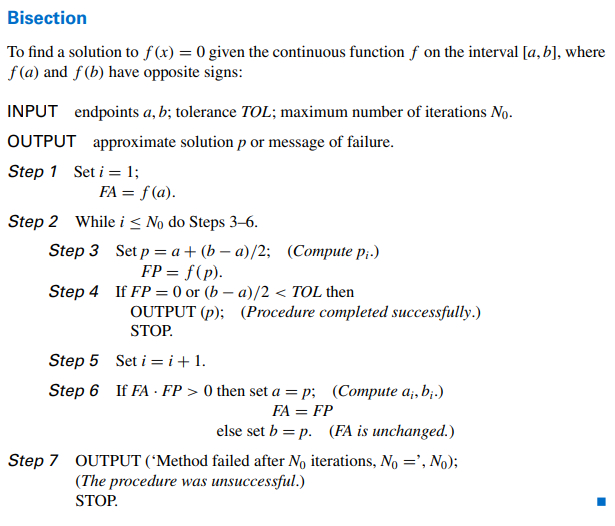

load data_bisection.mat
bisection_method(a,b,n)

1 th step approximate solution is 2.500000e+00

2 th step approximate solution is 2.750000e+00

3 th step approximate solution is 2.625000e+00

4 th step approximate solution is 2.687500e+00

5 th step approximate solution is 2.718750e+00

6 th step approximate solution is 2.734375e+00

7 th step approximate solution is 2.742188e+00

8 th step approximate solution is 2.738281e+00

9 th step approximate solution is 2.740234e+00

10 th step approximate solution is 2.741211e+00

11 th step approximate solution is 2.740723e+00

12 th step approximate solution is 2.740479e+00

13 th step approximate solution is 2.740601e+00

14 th step approximate solution is 2.740662e+00

15 th step approximate solution is 2.740631e+00

16 th step approximate solution is 2.740646e+00

17 th step approximate solution is 2.740639e+00

18 th step approximate solution is 2.740643e+00

19 th step approximate solution is 2.740644e+00

20 th step approximate solution is 2.740645e+00

21 th step approximate soluti

% a=2
% b=3
% n=100

function bisection_method(a, b, n)
    tolerance = 0.000000001;
    for i = 1:n
        y0 = func(a);
        y1 = func(b);
        if y0 == 0.0
            disp('the root is ', num2str(a));
            break
        elseif y1 == 0
            disp('the root is ', num2str(b));
            break
        elseif y0 * y1 > 0
            disp('Unsuitable input');
            break
        else
            c = (a + b) / 2;
            y2 = func(c);
            if y2 == 0.00
               disp('the root is ', num2str(c)); 
               break
            elseif y0 * y2 > 0
                a = c;
            else
                b = c;
            end 

            if abs(y1 - y0) < tolerance
                fprintf('The root is %d', c);
                break
            end

            fprintf('%d th step approximate solution is %d\n\n', i, c);
        end
    end
end

function f = func(x)
    f = x * log10(x) - 1.2;
end



